# Komposition von Regelstrecken - Positionsregelstrecke (PT1-I-Strecke)

In dieser Übung soll die Komposition von Regelstrecken untersucht werden. Konkret soll ein Positioniersystem, bestehend aus einem Gleichstrommotor (Km = 600(1/min)/V, T1=0,1s) einem nachgeschalteten Getriebe (Kg=1/10) und einer Spindel mit einer Ganghöge von g=3mm untersucht werden.

clear, close all, clc

s = tf('s'); % erstellen der komplexen Frequenz

## Gleichstrommotor (PT1-Strecke) mit Getriebe (P-Strecke)

Erstellen Sie Übertragungsfunktionen für den Motor Gm, das Getriebe Gg und deren Reihenschaltung Gmg. Stellen sie die Sprungantworten der Streckenteile sowie die Sprungantwort des Motor-Getriebe-Systems in drei Diagrammen untereinander dar. Stellen sie die Frequenzgänge in einem gemeinsamen Diagramm dar.

%<ToDo />
Km = 600;
T1 = 0.1;
Gm = Km/(1+s*T1)


Gm =
 
     600
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



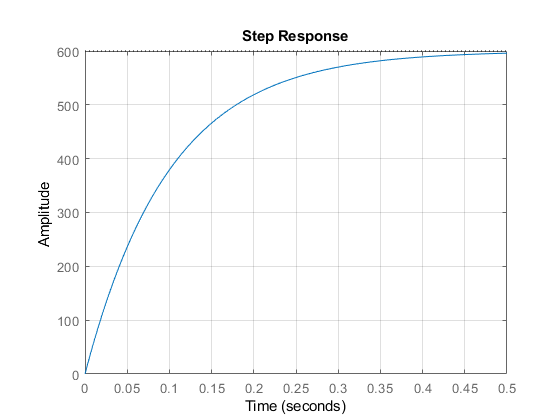


Tend = 5*T1;

%Getriebe
Kg = 1/10;
Gg = Kg*s^0;

figure,
step(Gm, Tend), grid on

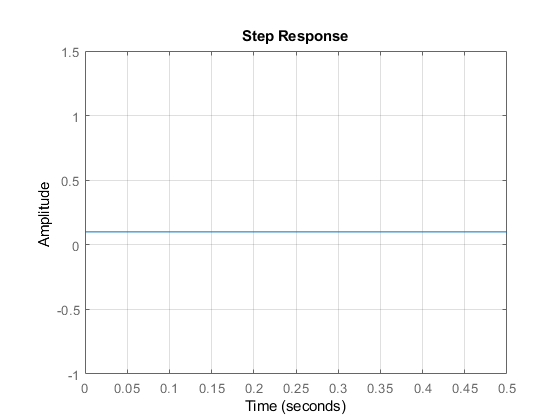

step(Gg, Tend), grid on

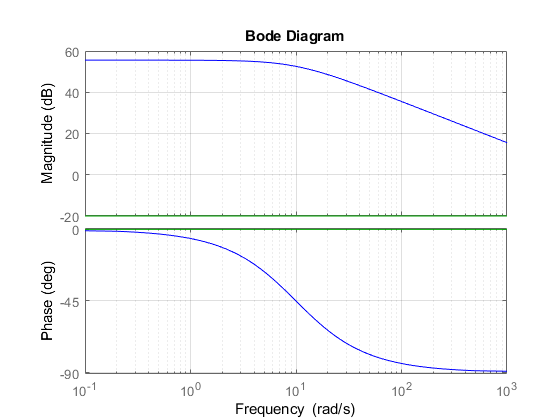


figure,
bode(Gm, 'b-', Gg, 'g-'), grid on

## Positioniersystem mit Spindelantrieb (I-Strecke)

Der Motor treibt über das Getriebe eine Spindel an. Der über die Spindel verschobene Schlitten entspricht einer I-Strecke. Leiten sie formal eine Beziehung zur Berechnung des Integrationsbeiwerts der I-Strecke her.

Die Verschubgeschw. des Schlittens lässt sich mit v = dx/dt = g/dt angeben. Bei einer Eingangsdrehzahl von n (min^-1) beträgt die Zeit für eine Umdrehung dt = 60 / n = womit sich die Änderungsgeschw. zu v = g/(60/n) [v] = mm/s ergibt. Der Intergrationsbeiwert Ksp = v/n wird damit zu Ksp = g/60 (mm/s)/(1/min)

%<ToDo />
g = 3; %Ganghöhe in mm
Ksp = g / 60;
Gsp = Ksp / s; % Übertragungsfunktion

Stellen sie die Sprungantworten für den Spindelantrieb und deren Frequenzgang untereinander dar.

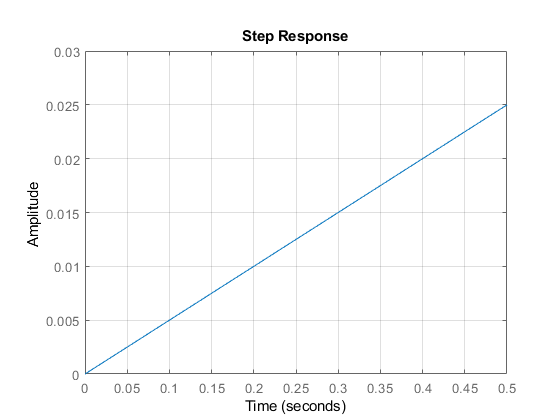

%<ToDo />
figure,
step(Gsp, Tend), grid on

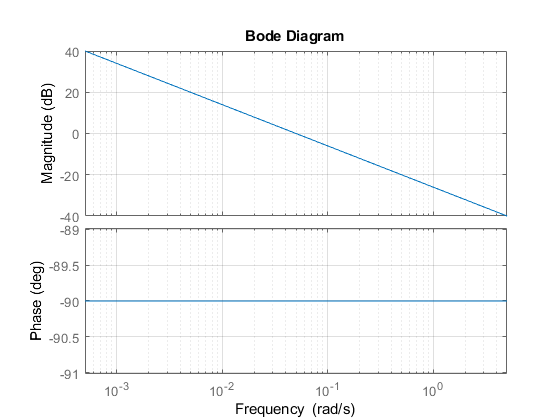

figure,
bode(Gsp, {Ksp/100, Ksp*100}), grid on

Stellen sie die Sprungantwort für Motor+Getriebe und die Sprungantwort für das Gesamtsystem übreinander dar.

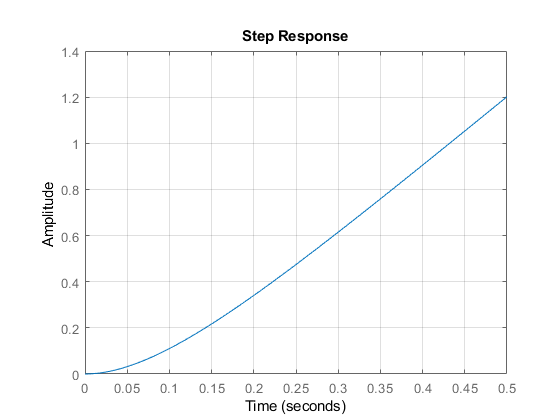

%<ToDo />
%Motor + Getriebe + Spindel
Gmgsp = Gm * Gg * Gsp;

figure
step(Gmgsp, Tend), grid on

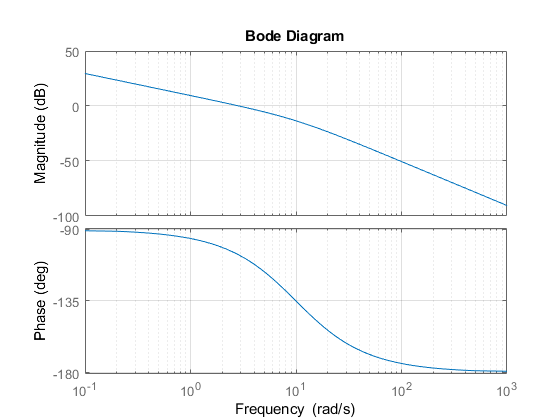

bode(Gmgsp), grid on

Stellen sie den Frequenzgang der einzelnen Streckenteile sowie den des Gesamtsystems in einem Diagramm dar.

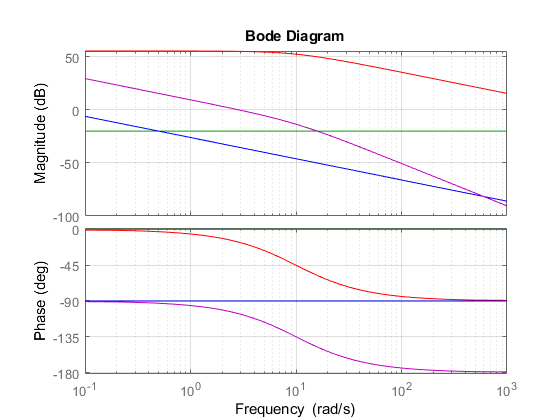

figure
bode(Gm, 'r', Gg, 'g', Gsp, 'b', Gmgsp, 'm'), grid on

## Symbolische Berechnung der Übertragungsfuntkion

Geben sie die Übertragungsfunktion der gesamten Strecke formal an.

%<ToDo />
% Ggesamt = Gm * Gg * Gsp